clear all ;

%read data in table tbl
tbl = readtable( "latinhypercube_all_ordered.dat", "Delimiter", "\t" , "TextType","string" ) ;


%extract data which correspond to 3 predictors as a matrix
predictor_data = tbl{:,2:4} ;


Parameters that define scaling of the original predictors (input variables):

predictor_data_norm = normalize( predictor_data )

predictor_data_norm =    -0.9521    1.0219    0.6695
   -0.1545    0.8619    0.2990
   -0.1512    0.7044    0.0081
    1.2629   -0.6009    0.9057
    0.9947   -1.1344   -1.2480
   -0.2989   -0.2154   -0.9527
   -1.1276    1.1242   -0.5739
    0.1858   -1.2160   -1.3833
   -1.6537   -1.6348    0.7116
   -1.3453    1.0887   -0.8095



[predictor_data_norm , mean_predictor_data , std_predictor_data ] = normalize( predictor_data ) ;

Load experimental data and ML models:

load gprMdl_opt_N_pt_1_all.mat

load gprMdl_opt_N_pt_2_all.mat

load gprMdl_opt_v2_all_grid.mat

load exp_data_PC.mat

load total_errors_lowpT.mat    

%err_N_pt_1    

%err_N_pt_2   

%err_v_2_4


%min_hyperparameters_data = 60.8761    0.2011    0.0204

%max_hyperparameters_data = 359.4388    1.1986    0.1995

lb = [61, 0.2, 0.02 ] ;

ub = [359, 1.2, 0.2 ] ;

lb_stan = ( lb - mean_predictor_data )./std_predictor_data

lb_stan =    -1.7141   -1.7270   -1.7274



ub_stan = ( ub - mean_predictor_data )./std_predictor_data

ub_stan =     1.7159    1.7269    1.7286




x0 = [300,  0.2 ,  0.3 ] ;

x0_stan = ( x0 - mean_predictor_data )./std_predictor_data

x0_stan =     1.0368   -1.7270    3.6487



 

N_v2_pred = @(x)[ ( predict(gprMdl_opt_N_pt_1_all,x) - principle_N_pt_1_exp )/err_N_pt_1 ; ( predict(gprMdl_opt_N_pt_2_all,x) - principle_N_pt_2_exp )/err_N_pt_2 ; ( predict(gprMdl_opt_v2_all_grid ,x) -  principle_v2_exp )/err_v_2_4 ]  ;

%[x_stan,~,r,~,~,~,J] = lsqnonlin( N_v2_pred,x0_stan,lb_stan,ub_stan ) ;

x_stan = lsqnonlin( N_v2_pred,x0_stan,lb_stan,ub_stan ) ;


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



%x_stan_ci = nlparci(x_stan,r,"Jacobian",J)

x = x_stan.*std_predictor_data + mean_predictor_data   

x =   102.4841    0.9004    0.1597


Generating Monte Carlo samples from drows according to errors:

n = 1000  ;

N = 100  ;

x0_mat = repmat(lb,N,1) + (repmat(ub,N,1)-repmat(lb,N,1)).*rand(N,3)

x0_mat =   211.1267    0.6067    0.1107
  206.8991    0.8669    0.1303
  322.3605    1.1337    0.1675
  166.2363    1.0110    0.1157
  194.9342    0.6845    0.0564
  348.1320    0.9567    0.1017
   73.6047    0.6170    0.0970
  350.9416    1.1718    0.1939
  117.3836    1.1880    0.1316
  259.8018    1.0641    0.1452



param_mat = []   ;

for i = 1:N

    x0_stan = x0_mat(i,:) ;

    for j = 1:n

        N_pt_1_pert = principle_N_pt_1_exp + random('Normal',0,err_N_pt_1) ;

        N_pt_2_pert = principle_N_pt_2_exp + random('Normal',0,err_N_pt_2) ;

        v2_pert = principle_v2_exp + random('Normal',0,err_v_2_4) ;

        param_mat = [ param_mat  ; [ x0_stan N_pt_1_pert N_pt_2_pert v2_pert ]  ] ;

    end

end

param_freq_mat = []


param_freq_mat =

     []




parfor i = 1:(N*n)

    x0_stan = param_mat(i,1:3)  ;

    N_pt_1_pert = param_mat(i,4)     ;

    N_pt_2_pert = param_mat(i,5)     ;

    v2_pert = param_mat(i,6)    ;

    %N_v2_pred = @(x)[ predict( gprMdl_opt_N_pt_1_all ,x) - N_pt_1_pert ; predict( gprMdl_opt_N_pt_2_all ,x) - N_pt_2_pert ; predict( gprMdl_opt_v2_all_grid , x ) - v2_pert ]  ;

    N_v2_pred = @(x)[ (predict( gprMdl_opt_N_pt_1_all ,x) - N_pt_1_pert)/err_N_pt_1 ; ( predict( gprMdl_opt_N_pt_2_all ,x) - N_pt_2_pert )/err_N_pt_2 ; ( predict( gprMdl_opt_v2_all_grid , x ) - v2_pert )/err_v_2_4 ]  ;

    x_stan = lsqnonlin( N_v2_pred,x0_stan,lb_stan,ub_stan ) ;

    x = x_stan.*std_predictor_data + mean_predictor_data    ;

    param_freq_mat = [ param_freq_mat ; x ]                                   ;

end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

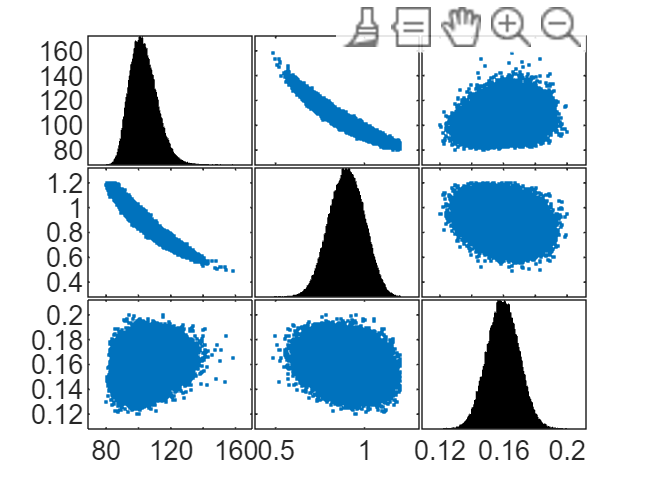


plotmatrix( param_freq_mat )  ;


param_freq_mat_weighted = param_freq_mat   ;

save param_freq_mat_weighted.mat  param_freq_mat_weighted    ;

%x_opt = [ 101.6  0.905  0.16 ]


Here save the maximum and errors to use them in Hamiltonian MC:

param_fraq_median_weight =  median( param_freq_mat )  ;

param_freq_std_weight = std( param_freq_mat  )   ;

save param_frequentionist_optimization_weight.mat    param_fraq_median_weight   param_freq_std_weight   ;
